# Week 3 - Data structures, file I/O and OOP

## 1. Week 2 recap - File I/O with .mat files

Among the things we covered in the week 2 problem set was how to read MATLAB variables from a `.mat` file into the workspace and then accessing these variables. For example, 

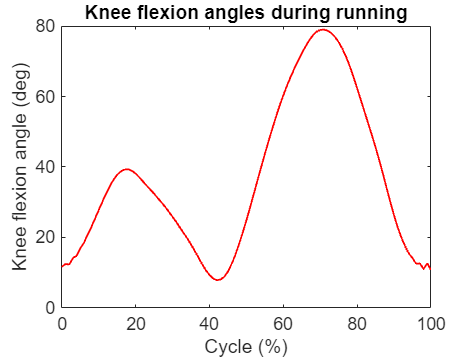

% Define filename
file_name = 'run_angles.mat';

% Load the variable 'knee_flx_ext' from file
load(file_name, 'knee_flx_ext');

% Plot the variable
figure();
plot(0:100, knee_flx_ext, 'r-', 'LineWidth', 1);
xlabel('Cycle (%)');
ylabel('Knee flexion angle (deg)');
title('Knee flexion angles during running');

Notive how the second argument `'knee_flx_ext'` is not only the name of a variable stored in the file, but also becomes the name MATLAB assigns to the variable loaded into the workspace. In other words, once the variable is loaded, you access its contents by calling the variabe `knee_flx_ext`. 

### 1.1. Loading multiple variables

The example above demonstrates how to load a single variable from a `.mat` file using MATLAB's `load()` function. However, we can also load multiple variables at once by separating the variable names with a comma.

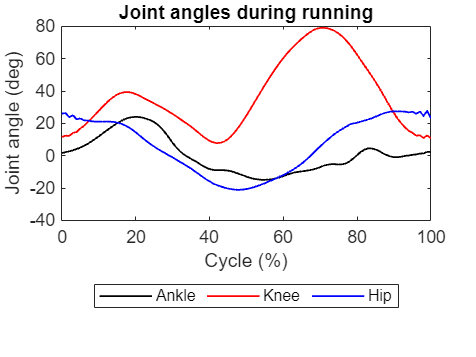

% Define filename
file_name = 'run_angles.mat';

% Load the variables 'ankle_df_pf', 'knee_flx_ext', and 
% 'hip_ext_flx' from file
load(file_name, 'ankle_df_pf', 'knee_flx_ext', 'hip_ext_flx');

% Plot the variable
figure();
t = 0:100;
plot(t, ankle_df_pf, 'k-', 'LineWidth', 1);
hold on;
plot(t, knee_flx_ext, 'r-', 'LineWidth', 1);
plot(t, hip_ext_flx, 'b-', 'LineWidth', 1);
xlabel('Cycle (%)');
ylabel('Joint angle (deg)');
legend({'Ankle', 'Knee', 'Hip'}, 'Location', 'southoutside', ...
    'Orientation', 'horizontal');
title('Joint angles during running');
hold off;

The variables we loaded above include all the variables in the file. When we want to load all variables, we can simply ommit the variable names alltogether.

% Clear all variables from the workspace
clear;

% Define filename
file_name = 'run_angles.mat';

% Load all variables from file
load(file_name);

% Plot the variable
figure();
t = 0:100;
plot(t, ankle_df_pf, 'k-', 'LineWidth', 1);
hold on;
plot(t, knee_flx_ext, 'r-', 'LineWidth', 1);
plot(t, hip_ext_flx, 'b-', 'LineWidth', 1);
xlabel('Cycle (%)');
ylabel('Joint angle (deg)');
legend({'Ankle', 'Knee', 'Hip'}, 'Location', 'southoutside', ...
    'Orientation', 'horizontal');
title('Joint angles during running');
hold off;

## 2. Structs, cells, and tables

So far so good! However, sometimes, you may not know the name of the variables you are loading into the workspace beforehand. In this case, it would be useful if you could change the variable name.

% Clear all variables from the workspace
clear;

% Define filename
file_name = 'run_angles.mat';

% Load all variables from file
data = load(file_name, 'knee_flx_ext');

However, when we try to access this data, we get an unexpected result

% Plot data
t = 0:100;
plot(t, data);

Error using plot
Unrecognized property knee_flx_ext for class Line.

### 2.1 MATLAB structures

The reason we are getting an error is that MATLAB's load function does not store the data in type that we have not encountered earlier when called with the syntax `var_name = load('file_name.mat', ...)`. Rather, MATLAB places the variable(s) you load into a new data type known as a structure.

fprintf('The class of "data" is "%s"\n', class(data));

Structures, or `struct` as MATLAB has named them, are MATLAB's implementation of a way of organizing data known more generally in computer science as a *dictionary*. Specifically, dictionaries store data as *key*,* value* pairs (similar to the concept that of name-value arguments that we used with the plotting functions). The main idea is that inside the struct, we can store multiple variables that each have a *key* and a *value*. For example, we can create a structure variable named `my_struct` containining the variables (keys; MATLAB calls them fields) named `x` with value `1`, `y` with value `'hello'`, and `z` with value `true `by using MATLAB's built-in function `struct()`.

my_struct = struct('x', 1, 'y', 'hello', 'z', true);

The values of each of the keys/fields in the structure can be accessed using the following syntax {*structure*`}.{``key/field``}`. 

fprintf('x = %i\n', my_struct.x);

x = 1


fprintf('y = %s\n', my_struct.y);

y = hello


fprintf('z = %i\n', my_struct.z);

z = 1


We can also create new fields in a structure using the "dot" syntax.

my_struct.v = [1 2 3];
disp(my_struct.v);

Notice that we can store variables containing entirely different native types in the keys/fields of a structure. As we saw in week 1, this was not the case for the native data types.

Finally, let's return to the variables we loaded from a file using `load()` and see how we can access them. 

% Define filename
file_name = 'run_angles.mat';

% Load all variables from file
data = load(file_name, 'knee_flx_ext');

% Plot the variable
figure();
plot(0:100, data.knee_flx_ext, 'r-', 'LineWidth', 1);
xlabel('Cycle (%)');
ylabel('Knee flexion angle (deg)');
title('Knee flexion angles during running');

As we can see in the example above, `load()` has taken the variable we loaded ('knee_flx_ext') and stored it as a key/field in the structure named `data`.

### 2.2. Cells

One of the convenient features of MATLAB structures is that they can store variables whose values have a different native type, all in one place. However, we do not always care about the *key/field* name (for example if what name we give the key has no practical meaning), in which case we might want omit it alltogether. MATLAB has another data type that can be used to store values of a different native type in one and the same variable, namely cell arrays. 

Cells can be created using a few different types of syntax, but the easiest is by using curly braces `{}`.

x = {1};
fprintf('x is of class %s\n', class(x));

 Now let's try accessing this value.

disp(x);

We are getting some strange syntax printed out. We can see our value, but its enclosed in a bunch of brackets. This is because MATLAB is giving us the entire cell, rather than the value stored inside it. To access the value stored in the cell, we use the curly braces again.

disp(x{1});

We can use cell arrays to store a bunch of different information and with various native types in each cell. For example, if we wanted to store a list that links a number with each of our lower extremity joints, we could do something link. 

joint{1, 1} = 1;
joint{1, 2} = 'ankle';
joint{2, 1} = 2;
joint{2, 2} = 'knee';
joint{3, 1} = 3;
joint{3, 2} = 'hip';
disp(joint);

### 2.3 MATLAB tables

Lastly, when dealing with research data, we often like to export out processed data in a format that is easy for humans to read and interpret. A MATLAB variable type that is particularly useful for this purpose is the `table()` type. Table variables largly resemble the tables we are familiar with from the world of spreadsheet software (like excel), but incorporated into MATLAB in a manner that makes it convenient to integrate it within a MATLAB programming workflow. 

Often, it is convenient to createa a table from variables we already have defined. For example,

% Define column arrays and vectors containing some data
id = {'P01'; 'P02'; 'P03'; 'P04'};
s = {'F'; 'F'; 'M'; 'F'};
a = [21; 32; 19; 28];
m = [53.2; 59.4; 78.7; 56.1];
h = [1.67; 1.65; 1.78; 1.57]; 

% Create table
demographics = table(id, s, a, m, h);
disp(demographics);

      id         s      a      m       h  
    _______    _____    __    ____    ____

    {'P01'}    {'F'}    21    53.2    1.67
    {'P02'}    {'F'}    32    59.4    1.65
    {'P03'}    {'M'}    19    78.7    1.78
    {'P04'}    {'F'}    28    56.1    1.57



By default, the columns of the table are named the same as the variable that was stored in it. However, we may want to give the columns more descriptive names. We can do this by setting the property `'VariableNames'`.

% Define variable names in a cell array
var_names = {'ID', 'Sex (M/F)', 'Age (yrs.)', 'Mass (kg)', 'Height (m)'};

% Create table
demographics = table(id, s, a, m, h, 'VariableNames', var_names);
disp(demographics);

      ID       Sex (M/F)    Age (yrs.)    Mass (kg)    Height (m)
    _______    _________    __________    _________    __________

    {'P01'}      {'F'}          21          53.2          1.67   
    {'P02'}      {'F'}          32          59.4          1.65   
    {'P03'}      {'M'}          19          78.7          1.78   
    {'P04'}      {'F'}          28          56.1          1.57   



We can index the variables in a few different ways in order to access a subset of variables. For example,

% Indexed like a regular MATLAB array
p01 = demographics(1, :); 
disp(p01);

      ID       Sex (M/F)    Age (yrs.)    Mass (kg)    Height (m)
    _______    _________    __________    _________    __________

    {'P01'}      {'F'}          21          53.2          1.67   




% Indexed using variable name
age = demographics(:, "Age (yrs.)");
disp(age);

    Age (yrs.)
    __________

        21    
        32    
        19    
        28    




% A combination of both
p03_mass = demographics(3, "Mass (kg)");
disp(p03_mass);

    Mass (kg)
    _________

      78.7   




% A collection of elements
p0304_mass_height = demographics(3:4, {'Mass (kg)', 'Height (m)'});
disp(p0304_mass_height);

    Mass (kg)    Height (m)
    _________    __________

      78.7          1.78   
      56.1          1.57   



Structs, cells, and tables are also very convenient types to work with when inputting and outputting data from/to files (file I/O).

## 3. File I/O for standard file formats

So far, we have loaded variables that "live" in a `.mat` file. But what if we want to access data from a different type of file? 

MATLAB's `load()` function can only handle `.mat` files, as well as very simple text files containing [ASCII symbols](https://www.asciitable.com/). Luckily, there is a whole other set of built-in MATLAB funcitons that can deal with other file formats. We will look at how we can load data from text files (`.csv`, `.tsv`, `.txt`, etc.), and spreadsheets (`.xlsx`).

### 3.1 Reading text files 

If we have numerical values in a text file, we can read it into MATLAB as a matrix using the `readmatrix()` function. If the file contains a header row (a row containing variable labels), this will be ignored.

% Define file name
file_name = 'squat01.txt';

% Read data from file into a matrix
mat = readmatrix(file_name);

% Display
head(mat, 5); % Shows the top 5 rows of the matrix

         0   38.8717   32.4575    1.3753   35.0216   27.6318   13.0364
    0.0167   43.3862   35.7410    2.6983   39.8582   31.5576   10.7889
    0.0333   46.0793   37.1911    5.1411   42.9164   34.0839   11.1086
    0.0500   48.7623   40.2324    9.7357   46.5665   39.1164   14.0044
    0.0667   51.0996   44.0993   14.6570   49.5175   43.8221   17.5016



If we are interested in retaining the header, we need to use a different function. One alternative is to read the data into a cell array using MATLAB's built-in function `readcell()`, and subsequently converting the numeric part to a matrix using the built-in function `cell2mat()`. 

% Remove matrix from previous example
clear mat;

% Define file name (notice that we are loading 
% a differnt file format. However, the functions,
% work the same for both .txt and .csv files. 
file_name = 'squat01.csv';

% Read data from file into cell array
C = readcell(file_name);
head(C, 5);

% Extract variable names from the first row
var_names = C(1,:);
disp(var_names);
disp(class(var_names));

% Convert everything from row 2 until the last row to a matrix
mat = cell2mat(C(2:end,:));
head(mat, 5);
disp(class(mat));

Lastly, we can read the data directly into a MATLAB using the built-in function `readtable()`.

% Define file name (notice that we are loading 
% a differnt file format. However, the functions,
% work the same for both .txt and .csv files. 
file_name = 'squat01.csv';

% Read data from file into table
tbl = readtable(file_name);
head(tbl, 5);

      time      hip_flexion_r    knee_angle_r    ankle_angle_r    hip_flexion_l    knee_angle_l    ankle_angle_l
    ________    _____________    ____________    _____________    _____________    ____________    _____________

           0       38.872           32.457          1.3753           35.022           27.632          13.036    
    0.016667       43.386           35.741          2.6983           39.858           31.558          10.789    
    0.033333       46.079           37.191          5.1411           42.916           34.084          11.109    
        0.05       48.762           40.232          9.7357           46.566           39.116          14.004    
    0.066667         51.1           44.099          14.657           49.518        

### 3.3. Reading data from spreadsheets

The three aformentioned functions can also be used to read data from excel spreadsheets. However, it is often most convenient to read these into a table. If your excel files have multiple sheets, we can use the `'Sheet'` name-value pair to specify which sheet we would like to load data from. 

% Specify file name
file_name = 'squat.xlsx';

% Read data from excel file
xls_tbl = readtable(file_name, 'Sheet', 'squat02');
head(xls_tbl, 5);

## 4. Writing data to files

In biomechanics research, we often deal with situations were we are interested in reading in data collected during an experiment, perform some form of data processing and reduction, and then outputing this data to a file that can be easily interpreted by humans. To achieve this task, we need to be able to output data from MATLAB.

For example, the files used to learn about file input above all contain joint angle data from the left and right ankle, knee, and hip during squatting. We might be interested in figuring out what the peak ankle dorsiflexion, knee flexion, and hip flexion, as well as the joint angular ranges of motion are for this task and export the data to an excel spreadsheet. We could achieve this with the following code.

% Specify file name
file_name = 'squat.xlsx';

% Read data from excel file
squat_data = readtable(file_name, 'Sheet', 'squat01');

% The built-in functions max() and range() both
% work on matrices (finds the value of interest in each
% row by default), so we can use these to find the peak 
% angles (lucky for us, ankle dorsiflexion, knee flexion,
% and hip flexion are all positive in this data), and joint
% angular range of motion.
max_tbl = max(squat_data(:, 2:end));
rng_tbl = range(squat_data(:, 2:end));
disp(max_tbl);

    hip_flexion_r    knee_angle_r    ankle_angle_r    hip_flexion_l    knee_angle_l    ankle_angle_l
    _____________    ____________    _____________    _____________    ____________    _____________

       116.24           132.31          37.202           118.16           132.09          48.924    



disp(rng_tbl);

    hip_flexion_r    knee_angle_r    ankle_angle_r    hip_flexion_l    knee_angle_l    ankle_angle_l
    _____________    ____________    _____________    _____________    ____________    _____________

       98.618           128.86          40.955           103.34           131.9           45.582    




% Let's sort these values by joint and create a nice table
joint = {'ankle'; 'knee'; 'hip'};
r_peak = max_tbl{:, 1:3}';
l_peak = max_tbl{:, 4:end}';
r_range = rng_tbl{:, 1:3}';
l_range = rng_tbl{:, 4:end}';
% notice the use of curly braces to access the vaule inside 
% each "cell" in the table.

var_names = {'Joint', 'Peak flexion right', 'Peak flexion left', ...
    'Range right', 'Range left'};
out_tbl = table(joint, r_peak, l_peak, r_range, l_range, ...
    'VariableNames', var_names);

% Now let's write this table to an excel file
writetable(out_tbl, 'squat_results.xlsx', 'FileType', 'spreadsheet');

We now have a file in the present working directory (the folder we have open in the "current folder" panel) named `squat_results.xlsx`. We can right-click this file and open it outside MATLAB to see that we indeed have an excel file with our results. 

We can also inspect our directory by using the `dir()` function, or store information about the files in a directory to a struct variable.

my_dir = dir('.\');
disp(dir);

This can be particularly helpful as we can use the structure provided by dir to construct file names for files we want to load. A convenient function to achieve this is `fullfile()` which combines these strings into a file path.

file_name = fullfile(my_dir(6).folder, my_dir(6).name);
disp(file_name);

## 5. A brief introduction to OOP

Object oriented programming (OOP) is a programming architechture/framework that is popular in many prgramming applications, including modelling of physical systems. Some programming languages are entirely based around OOP, such as C++ and Java, others support OOP, such as MATLAB and Python, whereas others do not support OOP at all, like C. 

OOP could be a whole course (or multiple courses) on its own, but we need to cover some basics here, as OpenSim (and its application programming interface) is written in C++ and is object oriented. 

The core idea in OOP is that you instead of having the normal data types we have seen we have individual *classes* that represent different physical or abstract objects. Instead of containing only one or a few values of one type, a class contains all the variables (called properties) and functions (called methods) that the class can use. The class serve as a sort of blueprint for variables of that class which are referred to as objects. 

The function `my_class.m` contains a simple class that can be created by providing x and y values of a function. It's method `draw()` plots the function.

% Define some input data
x = linspace(0, 2 * pi, 100);
y = sin(x);

% Instantiate object
my_obj = my_class(x, y);

% Access values stored in the property 'y'
head(my_obj.y', 5);

% Use the methods called 'draw'
my_obj.draw();

% Display class of my_obj
class(my_obj);

As we can seem both the *properties* (x and y) and *methods* (draw) are all contained in the *object* named `my_obj` and have class `my_class`. In other words, the data and the functions that operate on the data have all been packaged into one construct (class) and are kept toghether. Once we move into OpenSim, you will find that most *methods* we want to access are contained together with the *properties* of the *object* we are concerned with. We will revisit these consepts once we start working with OpenSim in MATLAB.